clear

subject = '17V'; % 13 and 14 same subject
load(strcat(pwd,'\Databases\Tilt\Registro_',subject,'.mat'),'datos');

Ecg.signal = datos{3,7}/10000;
Ecg.signal = Ecg.signal;
Ecg.samplerate = 1000;
Ecg.qrs = (datos{10,7}.qrs-20)/Ecg.samplerate;
Ecg.t = 0:1/Ecg.samplerate:(length(Ecg.signal)-1)/Ecg.samplerate;

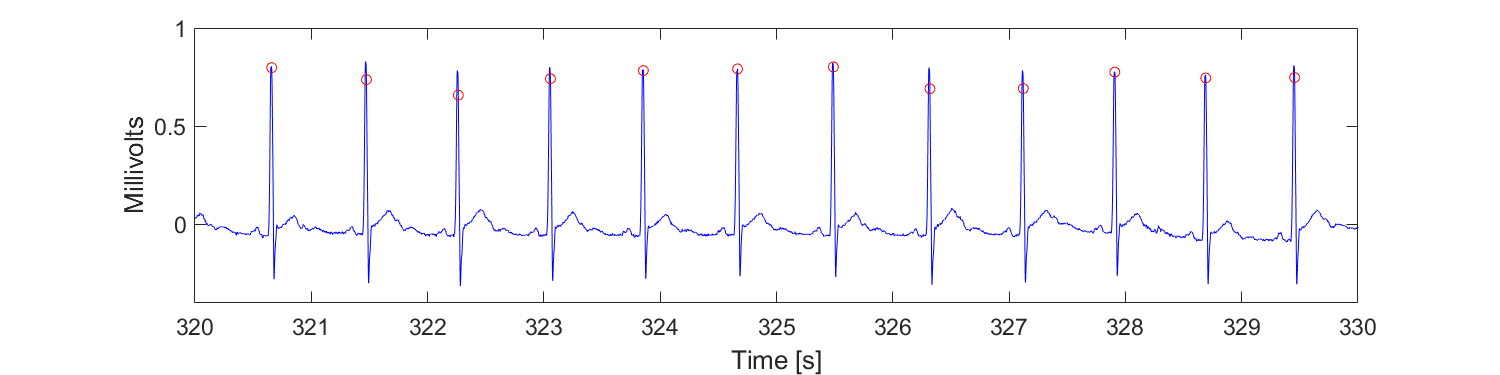

Error using matlab.internal.editor.FigureProxy/createNewWebFigureFromSerializedData
Error while evaluating Figure CreateFcn.



% figure('DefaultAxesFontSize',14)
% plot(Ecg.t,Ecg.signal,'b'); hold on
% plot(Ecg.qrs,Ecg.signal(round(Ecg.qrs*Ecg.samplerate)+1),'ro')
% xlabel("Time [s]")
% ylabel("Millivolts")
% axis tight
% xlim([320 330])
% ylim([-0.4 1])
% set(gcf,'position',[0,0,1200,300])

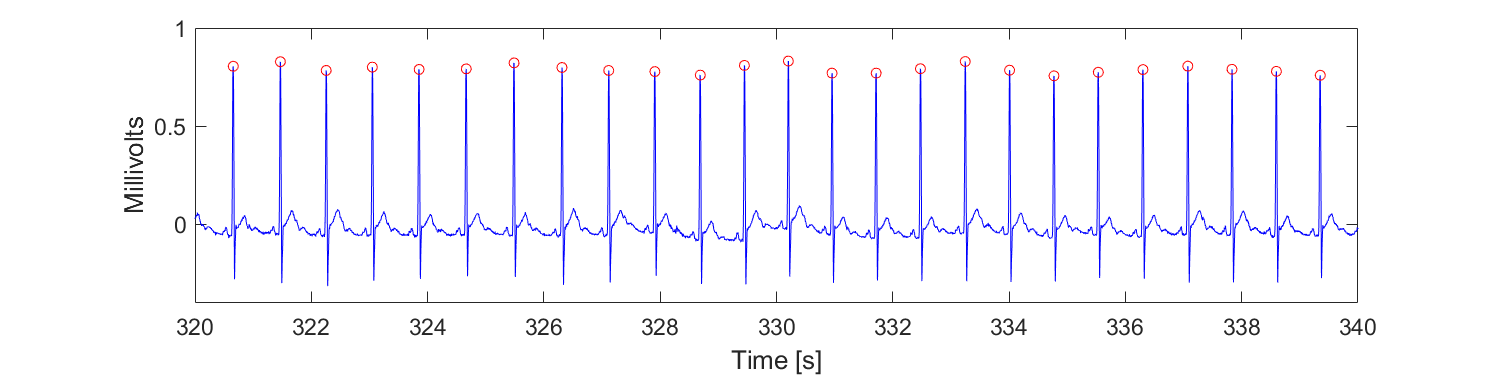

Error using matlab.internal.editor.FigureProxy/createNewWebFigureFromSerializedData
Error while evaluating Figure CreateFcn.



movetomax(Ecg.signal,Ecg.qrs,Ecg.samplerate); set(gcf,'position',[0,0,1200,300]);
xlim([320 340])
ylim([-0.4 1])
xlabel("Time [s]")
ylabel("Millivolts")

[bb, aa] = butter(3, 1*2/Fs, 'high');
ecg = filtfilt(bb, aa, mixture_of_noises(5,640000:658000));

[bb, aa] = butter(3, 9*2/Fs, 'low');
ecg = filtfilt(bb, aa, ecg);

t=0:1/Fs:(length(ecg)-1)/Fs;

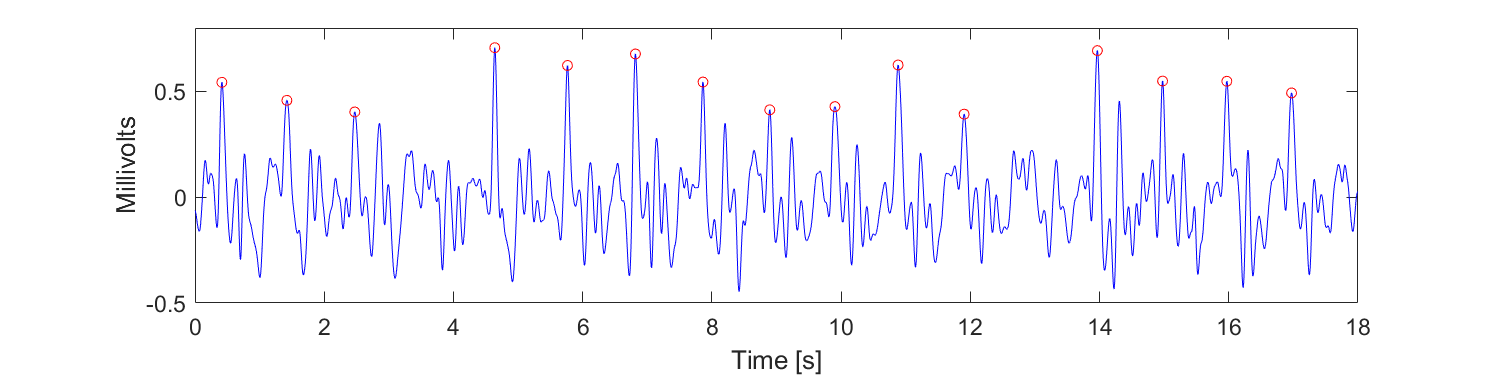

Error using matlab.internal.editor.FigureProxy/createNewWebFigureFromSerializedData
Error while evaluating Figure CreateFcn.



figure('DefaultAxesFontSize',14)
plot(t,ecg,'b'); hold on;
plot(qrs,ecg(round(qrs*Fs)+1),'ro')
axis tight
% xlim([644 658])
ylim([-0.5 0.8])
xlabel("Time [s]")
ylabel("Millivolts")
set(gcf,'position',[0,0,1200,300])

[bb, aa] = butter(3, 0.6*2/256, 'high');
ecg = filtfilt(bb, aa, sig1/1000);

% [bb, aa] = butter(3, 20*2/256, 'low');
% ecg = filtfilt(bb, aa, ecg);

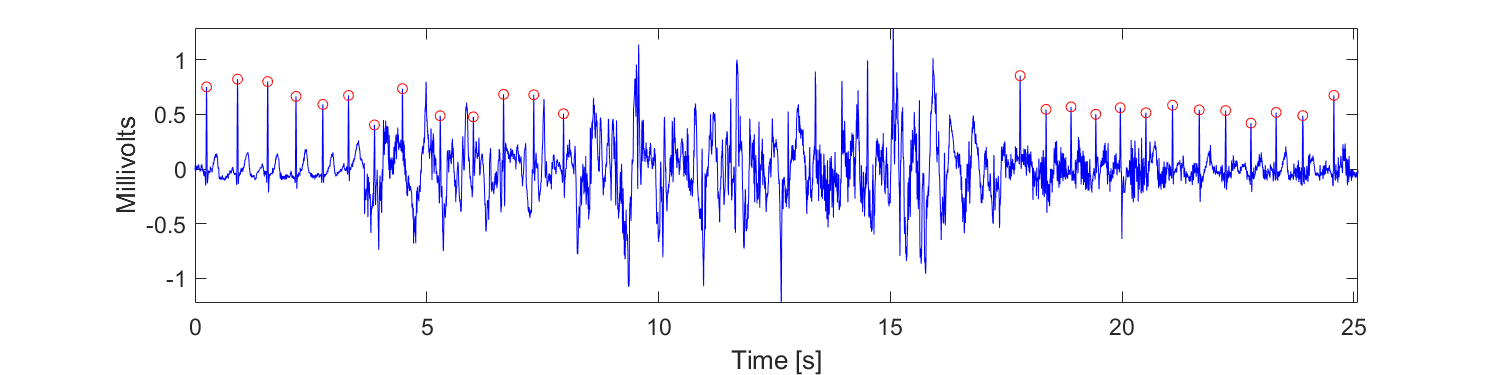

Error using matlab.internal.editor.FigureProxy/createNewWebFigureFromSerializedData
Error while evaluating Figure CreateFcn.



figure('DefaultAxesFontSize',14)
plot(t1,ecg,'b'); hold on;
plot(qrs,ecg(round(qrs*256)+1),'ro')
axis tight
% xlim([644 658])
% ylim([-0.5 0.8])
xlabel("Time [s]")
ylabel("Millivolts")
set(gcf,'position',[0,0,1200,300])